%http://correll.cs.colorado.edu/?p=1869
clear all
clc
W = 224 %mm

W = 224

L = 212 %mm

L = 212


global vs ws time xpoint ypoint psi
    vs = [];
    ws = [];
    time = [];
    xpoint = [];
    ypoint = [];
    psi = [0];

    allTimeActualx = [];
    allTimeDesiredVec = [];
    allTimeErrorVec = [];
    allT = [];
    %First Line
    Ti = 0;
    Tf=4; % Total Time
    actualInit=[1, 0, 0]; % Initial Condition where the robot starts.
    xdes_vecInit=[1, 0.5, 0]; %initial Desired configuration
    
    [actualx, xdes_vec, error_vec, tSteps] = followStraightLine(actualInit, xdes_vecInit, Ti, Tf, 0.5, 0);
    
    allTimeActualx = [allTimeActualx; actualx;];
    allTimeDesiredVec = [ allTimeDesiredVec; xdes_vec];
    allTimeErrorVec = [ allTimeErrorVec; error_vec];
    allT = [allT; tSteps];
    
    %Second Line
    Ti = Tf;
    Tf=8; % Total Time
    
    
    actualInit=allTimeActualx(end, :); % Initial Condition where the robot starts.
    xdes_vecInit=[3, 0.5, pi/2]; %initial Desired configuration
    
    [actualx, xdes_vec, error_vec, tSteps] = followStraightLine(actualInit, xdes_vecInit, Ti, Tf, 0, 0.5);
    
    allTimeActualx = [allTimeActualx; actualx;];
    allTimeDesiredVec = [ allTimeDesiredVec; xdes_vec];
    allTimeErrorVec = [ allTimeErrorVec; error_vec];
    allT = [allT; tSteps];
    
    %Third Line
    Ti = Tf;
    Tf=12; % Total Time

    actualInit=allTimeActualx(end, :); % Initial Condition where the robot starts.
    xdes_vecInit=[3, 2.5, pi]; %initial Desired configuration
    
    [actualx, xdes_vec, error_vec, tSteps] = followStraightLine(actualInit, xdes_vecInit, Ti, Tf, -0.5, 0);
    
    allTimeActualx = [allTimeActualx; actualx;];
    allTimeDesiredVec = [ allTimeDesiredVec; xdes_vec];
    allTimeErrorVec = [ allTimeErrorVec; error_vec];
    allT = [allT; tSteps];
    
    %Fourth Line
    Ti = Tf;
    Tf=16; % Total Time
    actualInit=allTimeActualx(end, :); % Initial Condition where the robot starts.
    xdes_vecInit=[1, 2.5, pi*3/2]; %initial Desired configuration
    
    [actualx, xdes_vec, error_vec, tSteps] = followStraightLine(actualInit, xdes_vecInit, Ti, Tf, 0, -0.5);
    
    allTimeActualx = [allTimeActualx; actualx;];
    allTimeDesiredVec = [ allTimeDesiredVec; xdes_vec];
    allTimeErrorVec = [ allTimeErrorVec; error_vec];
    allT = [allT; tSteps];
    disp(psi);

  Columns 1 through 22

         0    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854

  Columns 23 through 44

    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7478    0.7101    0.6738    0.6387    0.6048    0.5721    0.5405    0.5100    0.4806

  Columns 45 through 66

    0.4521    0.4246    0.3980    0.3722    0.3473    0.3232    0.2998    0.2772    0.2553    0.2340    0.2134    0.1934    0.1741    0.1553    0.1371    0.1194    0.1022    0.0856    0.0695    0.0538    0.0386    0.0239

  Columns 67 through 88

    0.0096   -0.0042   -0.0176   -0.0306   -0.0432   -0.0554   -0.0671   -0.0785   -0.0895   -0.1002   -0.1104   -0.1203   -0.1299   -0.1391   -0.1479   -0.1564   -0.1646   -0.1725   -0.1800   -0.1872   -0.1941   -0.2007

  Columns 89 

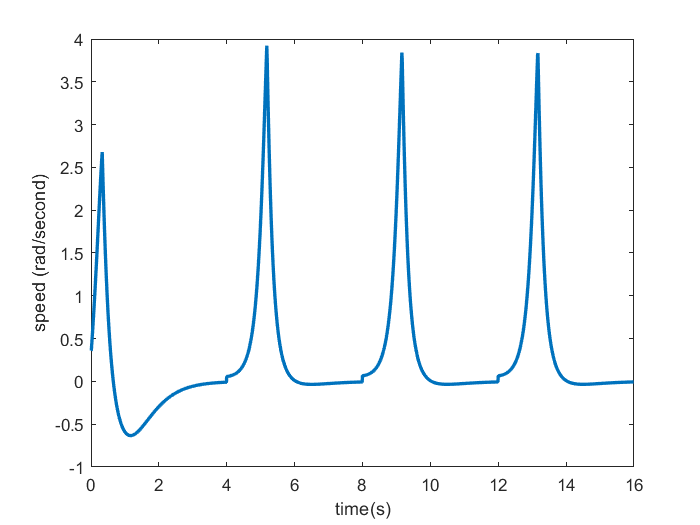

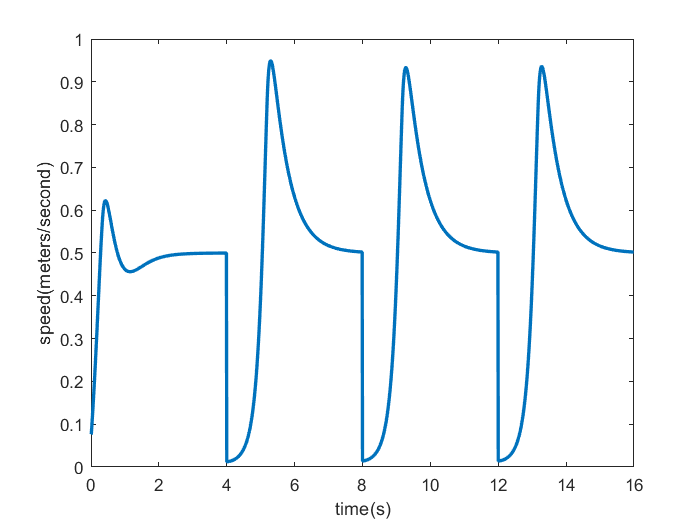

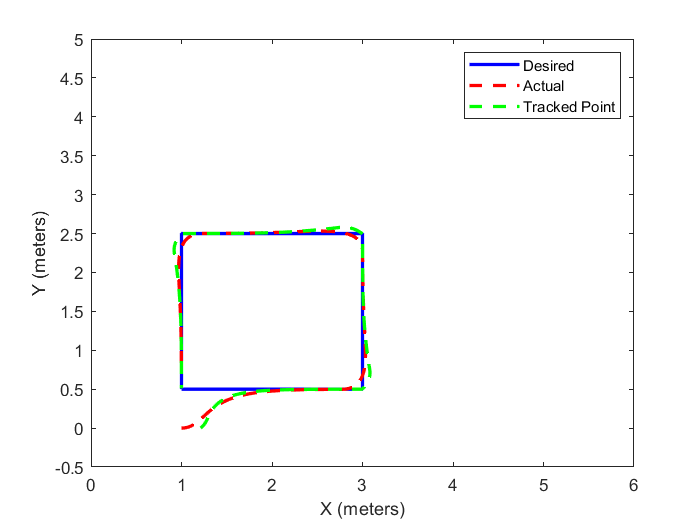

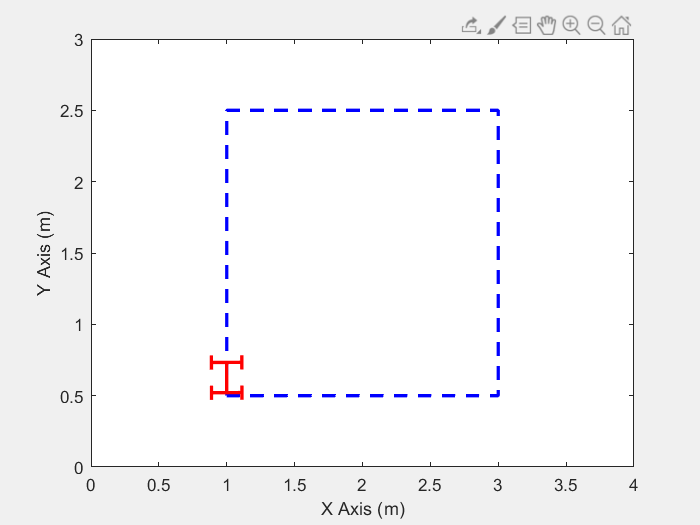

    

    plotStuff(allTimeActualx);

function [dx ] = errordynamics(t,x,y1Dotd, y2Dotd, y1d, y2d)
    global vs ws time xpoint ypoint
    carLength = .212;
    dr=.7; %zeta in textbook
    wd=0; 
    vd=1; 
    nf=1; %a in textbook
    b = 0.212; 
    k1=2;
    k2=2;
    dx=zeros(1,3);
    y1 = x(1)+b*cos(x(3));
    y2 = x(2)+b*sin(x(3));
    u1 = y1Dotd+k1*(y1d-y1);
    u2 = y2Dotd+k2*(y2d-y2);
    thetaDot = (u2*cos(x(3))-(u1*sin(x(3))))/b;
    f = [cos(x(3)), sin(x(3));-sin(x(3))/b, cos(x(3))/b]*[u1;u2];
    v = f(1);
    w = f(2);
    [v, w] = limiter(v, w, carLength, 3, pi/4);
    dx(1) = cos(x(3))*v;
    dx(2) = sin(x(3))*v;
    dx(3) = w;
    xpoint = [xpoint y1];
    ypoint = [ypoint y2];
    vs = [vs v];
    ws = [ws w];
    time = [time t];
end

function [actualx, xdes_vec, error_vec, tSteps] = followStraightLine(initial, desired, ti, tf, vdX, vdY)
    dt = 0.01;
    x = initial;%desired-initial;
    tSteps = ti:dt:tf;
    error_vec = x;
    xdes_vec = desired;
    temp = size(tSteps);
    for i=1:temp(2)-1
        % calculating the desired trajectory
        xdes= desired(1)+vdX*(tSteps(i)-ti);
        ydes= desired(2)+vdY*(tSteps(i)-ti);
        if(vdX==0.5)
           tdes=0 ;
        end
        if(vdX==-0.5)
           tdes=pi ;
        end
        if(vdY==0.5)
           tdes=pi/2 ;
        end
        if(vdY==-0.5)
           tdes=pi*3/2 ;
        end
        xdes_vec = [xdes_vec; [xdes, ydes, tdes]];
    end
    for i=1:temp(2)-1
         t = tSteps(i);
         [dx] = errordynamics(t,x, vdX, vdY, xdes_vec(i, 1), xdes_vec(i, 2)); % ode to solve edot=A*e
         x = x+dx*dt;
         error_vec = [error_vec; [x(1) x(2) x(3)]];
    end
    actualx = error_vec;

end
   
function [] = plotStuff(actualx)
    global vs ws time xpoint ypoint psi
    figure
    
    plot([1 3 3 1 1], [0.5 0.5 2.5 2.5 0.5],'b-', 'LineWidth', 2);
        xlim([0 6])
        ylim([-0.5 5])
    hold on 
    plot(actualx(:,1), actualx(:,2),'r--', 'LineWidth', 2);
    plot(xpoint, ypoint,'g--', 'LineWidth', 2);
    xlabel('X (meters)');
    ylabel('Y (meters)');
    legend('Desired', 'Actual', 'Tracked Point');
  
    figure
    plot(time, vs,'LineWidth', 2);
    xlim([0,16])
    ylabel('speed(meters/second)');
    xlabel('time(s)');
    
     figure
    plot(time, ws,'LineWidth', 2);
    xlim([0,16])
    ylabel('speed (rad/second)');
    xlabel('time(s)');
    
    numSecsForSim = 16;
    numSteps = 1600;

    timeDelay = numSecsForSim/numSteps;
    figure;
    set(gcf, 'Visible', 'on')
     plot([1 3 3 1 1], [0.5 0.5 2.5 2.5 0.5],'b--', 'LineWidth', 2);
        xlim([0 4])
        ylim([-0.5 3])
    hold on 
    
    carline = plot([actualx(1, 1),actualx(1, 1)+0.212*cos(actualx(1, 3));], [actualx(1, 2),actualx(1, 2)+0.212*sin(actualx(1, 3));], 'r-', 'LineWidth', 2);
    carRear = plot([actualx(1, 1) + 0.224/2*cos(actualx(1, 3)+pi/2), actualx(1, 1) + 0.224/2*cos(actualx(1, 3)-pi/2)], [actualx(1, 2) + 0.224/2*sin(actualx(1, 3)+pi/2), actualx(1, 2) + 0.224/2*sin(actualx(1, 3)-pi/2)], 'r-', 'LineWidth', 2);
    carFront = plot([actualx(1, 1)+0.212*cos(actualx(1, 3)) + 0.224/2*cos(actualx(1, 3)+pi/2), actualx(1, 1)+0.212*cos(actualx(1, 3)) + 0.224/2*cos(actualx(1, 3)-pi/2)], [actualx(1, 2)+0.212*sin(actualx(1, 3)) + 0.224/2*sin(actualx(1, 3)+pi/2), actualx(1, 2)+0.212*sin(actualx(1, 3)) + 0.224/2*sin(actualx(1, 3)-pi/2)], 'r-', 'LineWidth', 2);
    carRearLeftWheel = plot([actualx(1, 1) + 0.224/2*cos(actualx(1, 3)+pi/2) + 0.05*cos(actualx(1, 3)), actualx(1, 1) + 0.224/2*cos(actualx(1, 3)+pi/2) + 0.05*cos(actualx(1, 3)-pi)],[actualx(1, 2) + 0.224/2*sin(actualx(1, 3)+pi/2) + 0.05*sin(actualx(1, 3)), actualx(1, 2) + 0.224/2*sin(actualx(1, 3)+pi/2) + 0.05*sin(actualx(1, 3)-pi)],'r-', 'LineWidth', 2 );
    carRearRightWheel = plot([actualx(1, 1) + 0.224/2*cos(actualx(1, 3)-pi/2) + 0.05*cos(actualx(1, 3)), actualx(1, 1) + 0.224/2*cos(actualx(1, 3)-pi/2) + 0.05*cos(actualx(1, 3)-pi)],[actualx(1, 2) + 0.224/2*sin(actualx(1, 3)-pi/2) + 0.05*sin(actualx(1, 3)), actualx(1, 2) + 0.224/2*sin(actualx(1, 3)-pi/2) + 0.05*sin(actualx(1, 3)-pi)],'r-', 'LineWidth', 2 );
    [wheelLinex, wheelLiney] = calcTireLine(actualx(1, :), 0, psi(1));
    carFrontLeftWheel = plot(wheelLinex, wheelLiney,'r-', 'LineWidth', 2);
    
    [wheelLinex, wheelLiney] = calcTireLine(actualx(1, :), 1, psi(1));
    carFrontRightWheel = plot(wheelLinex, wheelLiney,'r-', 'LineWidth', 2);
    
    xlim([0, 4]);
    ylim([0, 3]);
    xlabel("X Axis (m)")
    ylabel("Y Axis (m)")
    
    for i = 1:numSteps+1
        pause(timeDelay);
        carline.XData = [actualx(i, 1),actualx(i, 1)+0.212*cos(actualx(i, 3));];
        carline.YData = [actualx(i, 2),actualx(i, 2)+0.212*sin(actualx(i, 3));];
        carRear.XData = [actualx(i, 1) + 0.224/2*cos(actualx(i, 3)+pi/2), actualx(i, 1) + 0.224/2*cos(actualx(i, 3)-pi/2)];
        carRear.YData = [actualx(i, 2) + 0.224/2*sin(actualx(i, 3)+pi/2), actualx(i, 2) + 0.224/2*sin(actualx(i, 3)-pi/2)];
        carFront.XData = [actualx(i, 1)+0.212*cos(actualx(i, 3)) + 0.224/2*cos(actualx(i, 3)+pi/2), actualx(i, 1)+0.212*cos(actualx(i, 3)) + 0.224/2*cos(actualx(i, 3)-pi/2)];
        carFront.YData = [actualx(i, 2)+0.212*sin(actualx(i, 3)) + 0.224/2*sin(actualx(i, 3)+pi/2), actualx(i, 2)+0.212*sin(actualx(i, 3)) + 0.224/2*sin(actualx(i, 3)-pi/2)];
        carRearLeftWheel.XData = [actualx(i, 1) + 0.224/2*cos(actualx(i, 3)+pi/2) + 0.05*cos(actualx(i, 3)), actualx(i, 1) + 0.224/2*cos(actualx(i, 3)+pi/2) + 0.05*cos(actualx(i, 3)-pi)];
        carRearLeftWheel.YData = [actualx(i, 2) + 0.224/2*sin(actualx(i, 3)+pi/2) + 0.05*sin(actualx(i, 3)), actualx(i, 2) + 0.224/2*sin(actualx(i, 3)+pi/2) + 0.05*sin(actualx(i, 3)-pi)];
        carRearRightWheel.XData = [actualx(i, 1) + 0.224/2*cos(actualx(i, 3)-pi/2) + 0.05*cos(actualx(i, 3)), actualx(i, 1) + 0.224/2*cos(actualx(i, 3)-pi/2) + 0.05*cos(actualx(i, 3)-pi)];
        carRearRightWheel.YData = [actualx(i, 2) + 0.224/2*sin(actualx(i, 3)-pi/2) + 0.05*sin(actualx(i, 3)), actualx(i, 2) + 0.224/2*sin(actualx(i, 3)-pi/2) + 0.05*sin(actualx(i, 3)-pi)];
        
        [wheelLinex, wheelLiney] = calcTireLine(actualx(i, :), 0, psi(i));
        carFrontLeftWheel.XData = wheelLinex;
        carFrontLeftWheel.YData = wheelLiney;
        
        [wheelLinex, wheelLiney] = calcTireLine(actualx(i, :), 1, psi(i));
        carFrontRightWheel.XData = wheelLinex;
        carFrontRightWheel.YData = wheelLiney;
    
    end
    
end

function [v, w] = limiter(v, w, carLength, vLim, maxSteerAngle)
global psi
    %limit Velocity
    if v>vLim
        v = vLim;
    elseif v < -vLim
        v = -vLim;
    end
    %Calc steering angle
    psit = atan(w*carLength/v);
    if psit > maxSteerAngle
        psit = maxSteerAngle;
    elseif psit < -maxSteerAngle
        psit = -maxSteerAngle;
    end
    w = tan(psit)/carLength*v;
    psi = [psi psit];
end

function [linex, liney] = calcTireLine(st, wheel, psi)

carLength = 0.212;
carWidth = 0.224;
R = carLength*tan(psi+pi/2);
if(wheel == 0) %leftWheel
    wheelPsi = -((atan(carLength/(R+carWidth/2))));
    linex = [st(1)+0.212*cos(st(3)) + 0.224/2*cos(st(3)+pi/2) + 0.05*cos(st(3)+wheelPsi), st(1)+0.212*cos(st(3)) + 0.224/2*cos(st(3)+pi/2)+ 0.05*cos(st(3)+wheelPsi - pi)];
    liney = [st(2)+0.212*sin(st(3)) + 0.224/2*sin(st(3)+pi/2) + 0.05*sin(st(3)+wheelPsi), st(2)+0.212*sin(st(3)) + 0.224/2*sin(st(3)+pi/2)+ 0.05*sin(st(3)+wheelPsi - pi)];
else
    wheelPsi = -((atan(carLength/(R-carWidth/2))));
    linex = [st(1)+0.212*cos(st(3)) - 0.224/2*cos(st(3)+pi/2) + 0.05*cos(st(3)+wheelPsi), st(1)+0.212*cos(st(3)) - 0.224/2*cos(st(3)+pi/2)- 0.05*cos(st(3)+wheelPsi)];
    liney = [st(2)+0.212*sin(st(3)) - 0.224/2*sin(st(3)+pi/2) + 0.05*sin(st(3)+wheelPsi), st(2)+0.212*sin(st(3)) - 0.224/2*sin(st(3)+pi/2)- 0.05*sin(st(3)+wheelPsi)];
end

end
